
	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "rescaled" behaviour IS ongoing.
Using current obj.cc_mode : rescaled_peaks


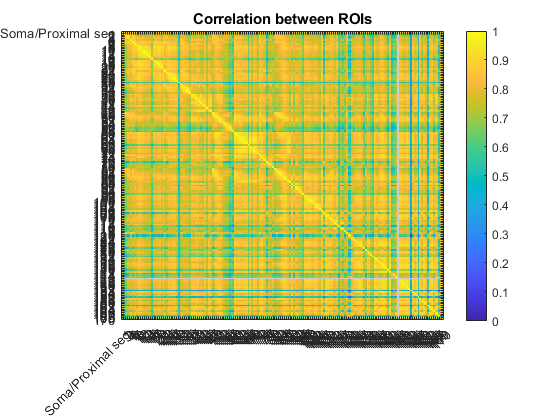

Using current obj.cc_mode : rescaled_peaks
total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

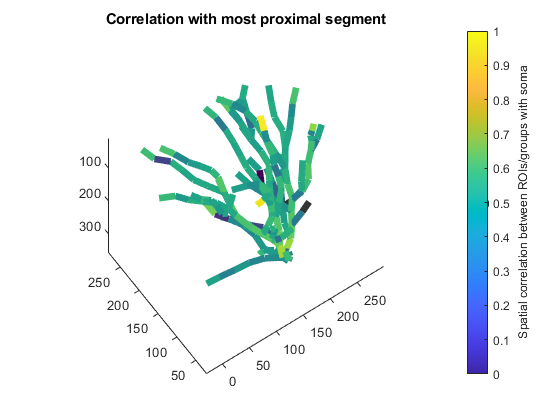

obj.filter_win = [10, 0];
obj.get_correlations('rescaled_peaks');


	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "subtracted" behaviour IS ongoing.
Using current obj.cc_mode : subtracted_peaks


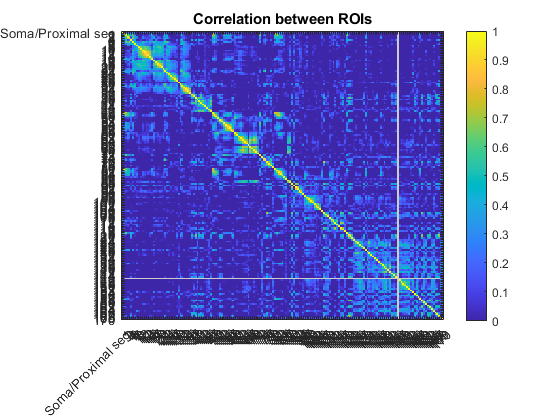

Using current obj.cc_mode : subtracted_peaks
total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

obj.get_correlations('subtracted_peaks'); hold on

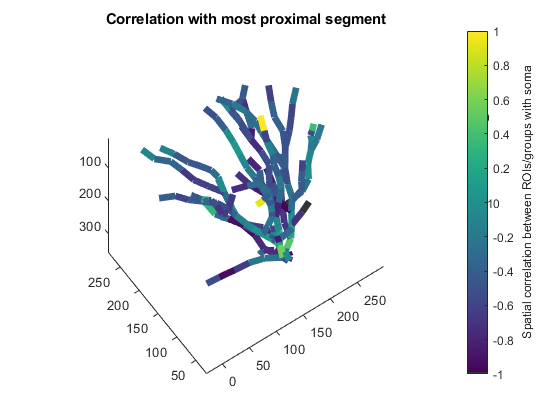

caxis([-1,1])


	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "subtracted" behaviour IS ongoing.
Using current obj.cc_mode : subtracted_peaks


Using current obj.cc_mode : subtracted_peaks
total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

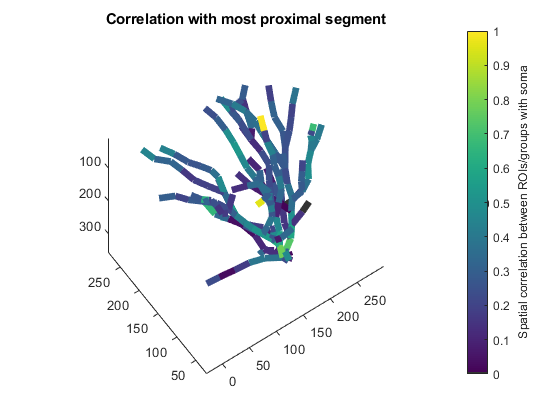

cross_corr = 171×171 single matrix
    1.0000   -0.0292    0.1592    0.1541    0.2272    0.1792    0.2856    0.2079   -0.0232    0.0399    0.1017    0.2485    0.1940    0.1508    0.1253    0.1293   -0.0202    0.1750    0.1600    0.0972    0.0916    0.1206    0.3045    0.1951    0.1741    0.0935    0.0440    0.0115    0.0811    0.1000   -0.5393    0.1230    0.2417    0.1651    0.0818   -0.0386   -0.1087    0.0650   -0.2275   -0.0234   -0.0945    0.0525   -0.1169   -0.0339    0.0648   -0.2978    0.0082   -0.0281    0.1064    0.2478
   -0.0292    1.0000    0.5787    0.3729    0.2833    0.2549    0.1903    0.1542    0.0058   -0.1690   -0.1139   -0.1631   -0.1818   -0.0732   -0.1204    0.0239    0.4020   -0.0373   -0.0887   -0.0422   -0.0243   -0.1150   -0.0116    0.2991    0.0500   -0.1131   -0.1314   -0.1400   -0.1747    0.0242    0.0191    0.1793    0.2027    0.0768   -0.0158   -0.0517   -0.0350    0.1616    0.0312    0.1023   -0.0489    0.1399   -0.0231    0.1456    0.0790    0.0511   -

cross_corr = obj.get_correlations('subtracted_peaks')

% Note : you need to add to the path GenLouvain-master
[S,Q] = genlouvain(double(cross_corr),[],[],1);

Merging 171 communities  06-Oct-2022 16:24:01
15 change: 640.1203 total: 640.1203 relative: 1
6 change: 104.2027 total: 744.323 relative: 0.14
6 change: 3.3778 total: 747.7008 relative: 0.0045176
6 change: 0 total: 747.7008 relative: 0
Merging 6 communities  06-Oct-2022 16:24:01
5 change: 15.3833 total: 763.0841 relative: 0.020159
5 change: 0 total: 763.0841 relative: 0
Merging 5 communities  06-Oct-2022 16:24:01
5 change: 0 total: 763.0841 relative: 0


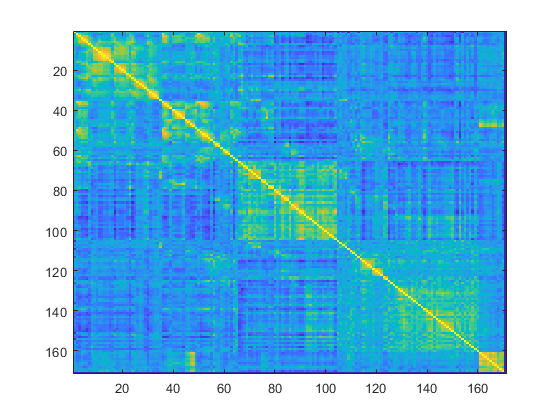

[a,b] = sort(S);
figure(1008);clf();imagesc(cross_corr(b,b))

obj.ref.plot_value_tree(S,'','','CC-based clusters','',124,'','lines');

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

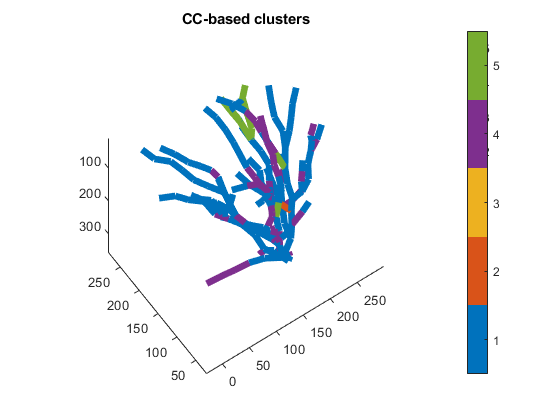

R = unique(S);
colorbar('Ticks',R);
caxis([nanmin(R)-0.5, nanmax(R)+0.5])
colormap(lines(numel(unique(S))));

% 
% [S,Q] = genlouvain(double(cross_corr),[],[],1);
% [a,b] = sort(S);
% figure(1008);clf();imagesc(cross_corr(b,b))
% obj.ref.plot_value_tree(split_values_per_voxel(S, obj.ref.header.res_list(1:obj.ref.indices.n_tree_ROIs,1), signal_indices),'','','','',124,'','lines');
% R = unique(S);
% colorbar('Ticks',R);
% caxis([nanmin(R)-0.5, nanmax(R)+0.5])
% colormap(lines(numel(unique(S))));